clear

# First assignment

% Load parameters
load_parameters;

% Define the simulation time step
dt = 0.05;

% Start recording how much time the simulation takes
tic

% Pre-allocate arrays to store simulation results
time = 50.0;
% tSpan = linspace(0, time, time/dt); % Time vector with sampling rate of 100Hz
num_steps = time / dt;
t_result = zeros(num_steps, 1); % Time vector to store simulation time
x_result = zeros(num_steps, 2); % Matrix to store magnet position and velocity

u = 0; % Setting a null system input 
 
for c = 1.41:0.01:1.42
    z0 = params.z_eq + c;

    % Control loop
    t_current = 0.0;
    x_current = [z0; 0]; % Initial state vector [position; velocity]
    for i = 1:num_steps
        % Store current time and state
        t_result(i) = t_current;
        x_result(i, :) = x_current;
        
        % Update state using ODE integration
        [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
        
        % Update current time and state for next iteration
        t_current = t_out(end);
        x_current = x_out(end, :);
    
    end % for i = 1:num_steps

### Plotting results

We plot the position of the center of the magnet to see the results of the simulation.

Simulation time: 0.56s


z0: 1.46m


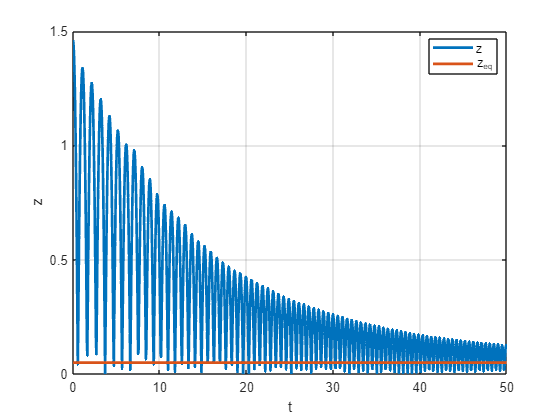

Simulation time: 1.07s


z0: 1.47m


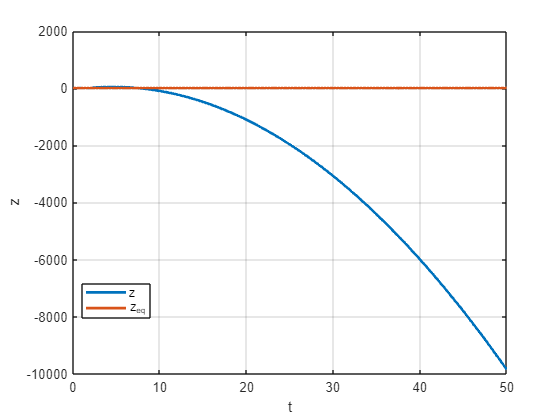

    fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time
    
    figure;
    clf; grid on; hold on; box on;
    
    fprintf('z0: %.2fm\n', z0) 
    plot(t_result, x_result(:, 1),'linewidth',2)
    plot(t_result, params.z_eq * ones(num_steps,1),'linewidth',2)
    legend({'z','z_{eq}'},'location','best')
    xlabel('t')
    ylabel('z')
end % for c = 1.41:0.01:1.42

clear

# Second assignment

% Load parameters
load_parameters;

% Define the simulation time step
dt = 0.1;

% Start recording how much time the simulation takes
tic

% Initialize variables for control loop
z0 = params.z_eq % Initial condition for magnet position 

z0 = 0.0500

% Initialize open loop
numerator = params.b_s/params.z_eq

numerator = 20

denominator = [params.m params.d params.b_m/(params.z_eq)^2]

denominator =     0.0770    0.0001   15.1074


sys_open = tf(numerator,denominator) % requires the Control System Toolbox add-on

sys_open =
 
               20
  ----------------------------
  0.077 s^2 + 0.0001 s + 15.11
 
Continuous-time transfer function.
Model Properties


## Root Locus

We plot the root locus of the open loop.

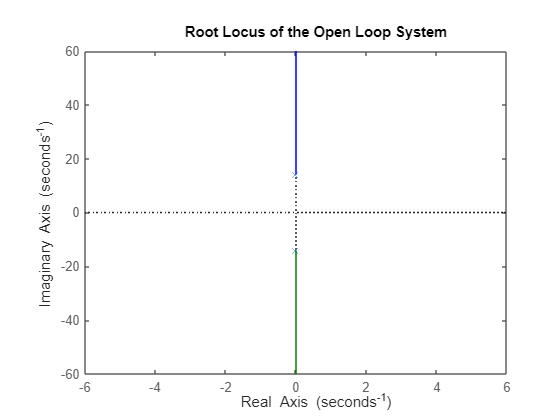

figure;
rlocus(sys_open);
title('Root Locus of the Open Loop System');

## Settling Time

% Array of K values to test
K_values = [1, 5, 10, 50, 100, 200, 500, 1000, 2000, 5000, 10000];

% Pre-allocate arrays to store simulation results
settling_times = zeros(size(K_values));

% Get the settling time for evey K value
for i = 1:length(K_values)
    K = K_values(i);
    
    sys_closed = feedback(K * sys_open, 1);

    step_info = stepinfo(sys_closed);
    settling_times(i) = step_info.SettlingTime;
end % for i = 1:length(K_values)

We plot the Settling Time for every K value we selected.

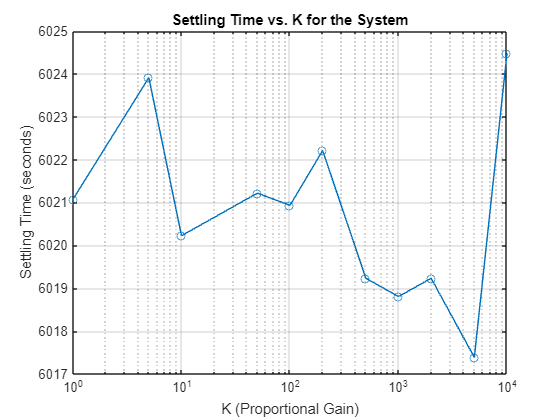

figure;

semilogx(K_values, settling_times, '-o');
xlabel('K (Proportional Gain)');
ylabel('Settling Time (seconds)');
title('Settling Time vs. K for the System');
grid on;

We find the minimum settling time and the corresponding K value.

[min_settling_time, min_index] = min(settling_times);
Kp = K_values(min_index);
C = Kp

C = 5000

## Step response simulation

We plot the step response fo the lineaized system

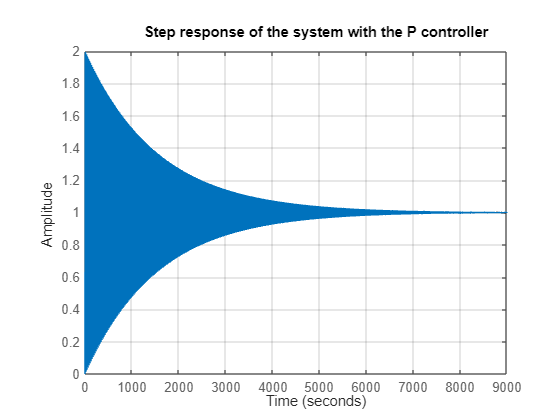

sys_closed = feedback(C * sys_open, 1);
figure;
step(sys_closed);
grid on;
title('Step response of the system with the P controller');

disp(['Minimum Settling Time: ', num2str(min_settling_time), ' seconds at K = ', num2str(Kp)]);

Minimum Settling Time: 6017.3884 seconds at K = 5000


## Simulation

% Pre-allocate arrays to store simulation results
time = 1000.0;
% tSpan = linspace(0, time, time/dt); % Time vector with sampling rate of 100Hz
z_ref = params.z_eq + 0.02; % Reference position for control
num_steps = time/dt;
t_result = zeros(num_steps, 1); % Time vector to store simulation time
x_result = zeros(num_steps, 2); % Matrix to store magnet position and velocity

% Control loop
t_current = 0.0;
x_current = [z0; 0]; % Initial state vector [position; velocity]
for j = 1:length(K_values)
    for i = 1:num_steps
        % Calculate error
        error = z_ref - x_current(1);
        
        % Calculate control signal
        u = K_values(j)*error;
    
        % Store current time and state
        t_result(i) = t_current;
        x_result(i, :) = x_current;
        
        % Update state using ODE integration
        [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
        
        % Update current time and state for next iteration
        t_current = t_out(end);
        x_current = x_out(end, :);
    
    end % for i = 1:num_steps
    
    fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time

### Plotting results

We plot the position of the center of the magnet to see the results of the simulation. 

Simulation time: 12.54s


Kp:1


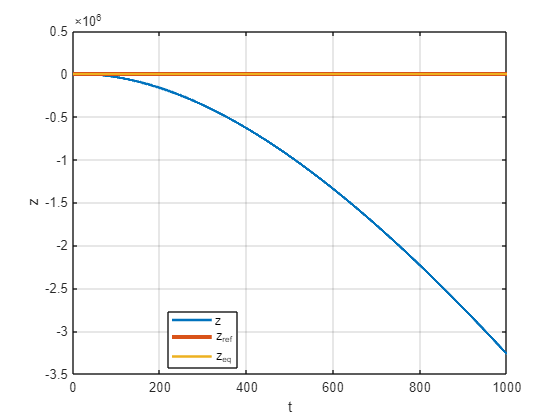

Simulation time: 18.14s


Kp:5


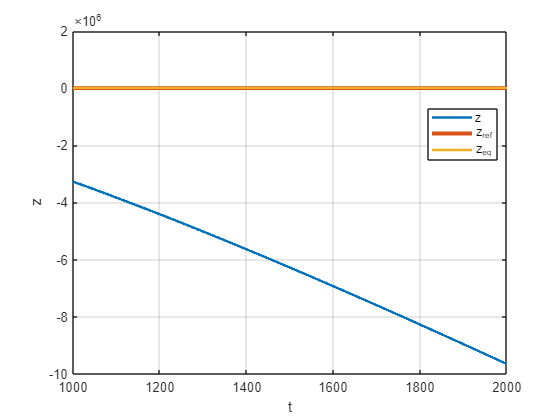

Simulation time: 22.52s


Kp:10


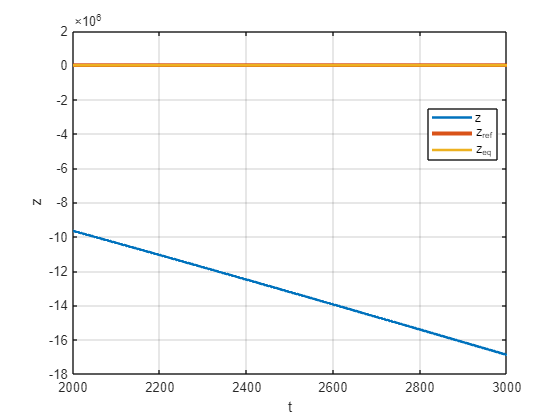

Simulation time: 26.74s


Kp:50


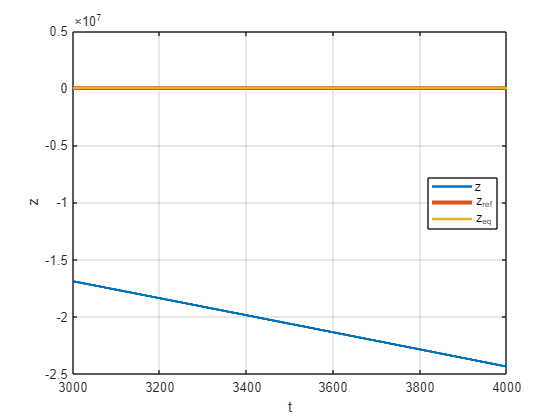

Simulation time: 31.61s


Kp:100


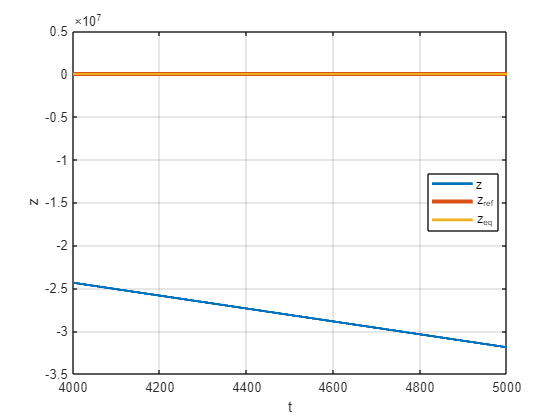

Simulation time: 36.73s


Kp:200


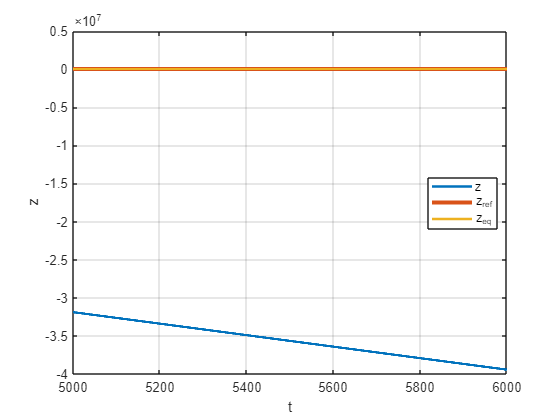

Simulation time: 40.69s


Kp:500


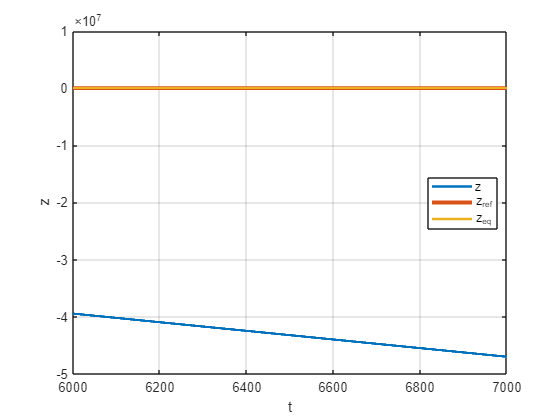

Simulation time: 44.67s


Kp:1000


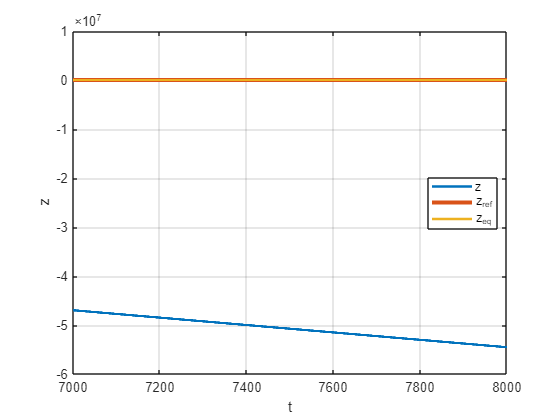

Simulation time: 48.24s


Kp:2000


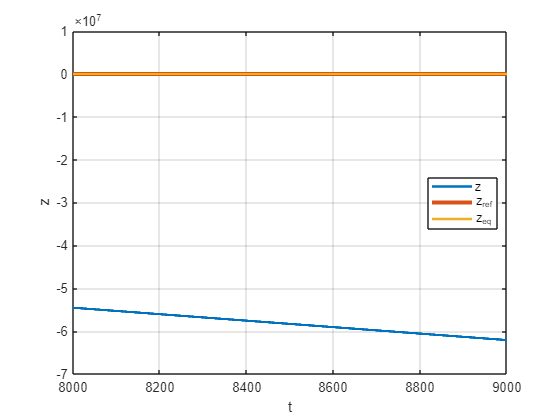

Simulation time: 51.50s


Kp:5000


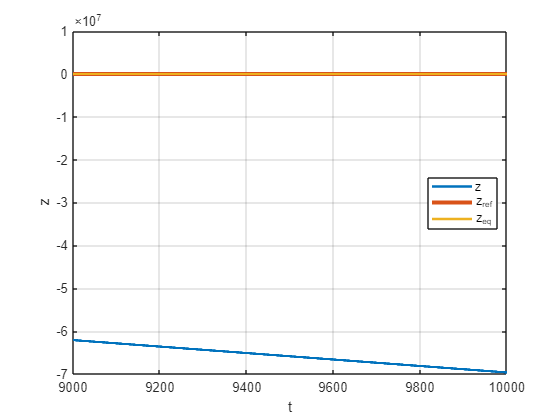

Simulation time: 54.79s


Kp:10000


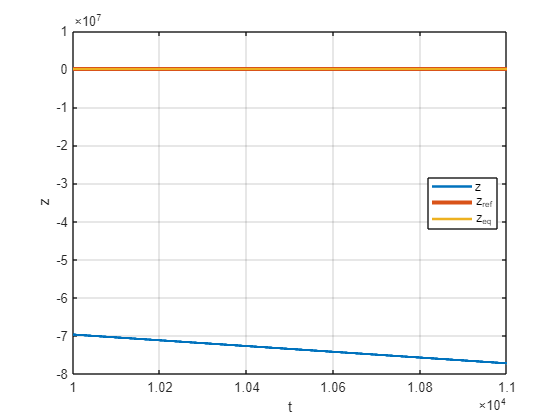

    disp(['Kp:', num2str(K_values(j))]);
    figure;
    clf; grid on; hold on; box on;
    plot(t_result, x_result(:, 1),'linewidth',2)
    plot(t_result, z_ref * ones(num_steps,1),'linewidth',3)
    plot(t_result, params.z_eq * ones(num_steps,1),'linewidth',2)
    legend({'z','z_{ref}','z_{eq}'},'location','best')
    xlabel('t')
    ylabel('z')
end % for j = 1:length(K_values)

clear

# Third assignment

% Load parameters
load_parameters;

% Define the simulation time step
dt = 0.01;

% Start recording how much time the simulation takes
tic

% Initialize variables for control loop
prev_error = 0;
integral = 0;
z0 = params.z_eq; % Initial condition for magnet position

% Initialize open loop
numerator = params.b_s/params.z_eq;
denominator = [params.m params.d params.b_m/(params.z_eq)^2];
sys_open = tf(numerator,denominator);

## Create the PID controller

% pidTuner(sys_open, 'PID') % requires the Control System Toolbox add-on
Kp = 5.0;
Ki = 14;
Kd = 0.45;
C = pid(Kp,Ki,Kd);

% Closed loop
sys_closed = feedback(C*sys_open,1);

## Step response simulation

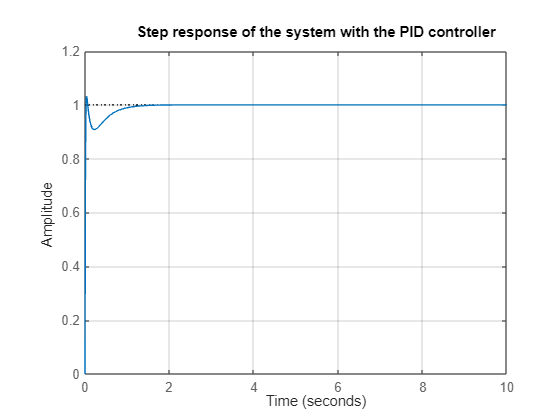

figure;
t = 0:0.01:10;
step(sys_closed, t);
grid on;
title('Step response of the system with the PID controller');

## Verification of stability margins

We plot the Bode Plot of the closed loop.

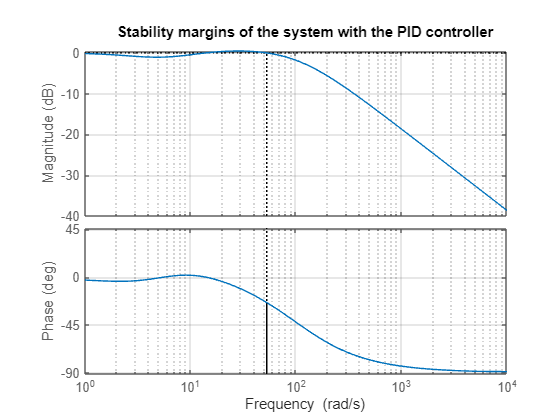

figure;
margin(sys_closed);
grid on;
title('Stability margins of the system with the PID controller');

## Simulation

% Pre-allocate arrays to store simulation results
time = 10.0;
% tSpan = linspace(0, time, time/dt); % Time vector with sampling rate of 100Hz
z_ref = params.z_eq + 0.02; % Reference position for control
num_steps = time/dt;
t_result = zeros(num_steps, 1); % Time vector to store simulation time
x_result = zeros(num_steps, 2); % Matrix to store magnet position and velocity

% Control loop
t_current = 0.0;
x_current = [z0; 0]; % Initial state vector [position; velocity]
for i = 1:num_steps
    % Calculate error
    error = z_ref - x_current(1);
    
    % Calculate integral and derivative terms
    integral = integral + error * dt;
    derivative = (error - prev_error) / dt;
    
    % Calculate control signal using PID controller
    u = Kp * error + Ki * integral + Kd * derivative;
    
    % Update previous error
    prev_error = error;
    
    % Store current time and state
    t_result(i) = t_current;
    x_result(i, :) = x_current;
    
    % Update state using ODE integration
    [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
    
    % Update current time and state for next iteration
    t_current = t_out(end);
    x_current = x_out(end, :);
end

fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time

Simulation time: 1.52s


### Plotting results

We plot the position of the center of the magnet to see the results of the simulation. 

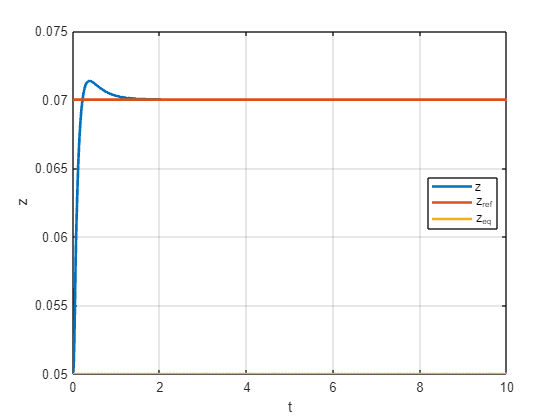

figure;
clf; grid on; hold on; box on;

plot(t_result, x_result(:, 1),'linewidth',2)
plot(t_result, z_ref * ones(num_steps,1),'linewidth',2)
plot(t_result, params.z_eq * ones(num_steps,1),'linewidth',2)
legend({'z','z_{ref}','z_{eq}'},'location','best')
xlabel('t')
ylabel('z')

clear

# Fourth assignment

% Load parameters
load_parameters;

% Define the simulation time step
dt = 0.01;

% Start recording how much time the simulation takes
tic

% Initialize variables for control loop
prev_error = 0;
integral = 0;
z0 = params.z_eq; % Initial condition for magnet position

% Initialize open loop
numerator = params.b_s/params.z_eq;
denominator = [params.m params.d params.b_m/(params.z_eq)^2];
sys_open = tf(numerator,denominator);

## Create the PID controller

% pidTuner(sys_open, 'PID') % requires the Control System Toolbox add-on
Kp = 5;
Ki = 24;
Kd = 0.45;
C = pid(Kp,Ki,Kd);

% Closed loop
sys_closed = feedback(C*sys_open,1);

## Step response simulation

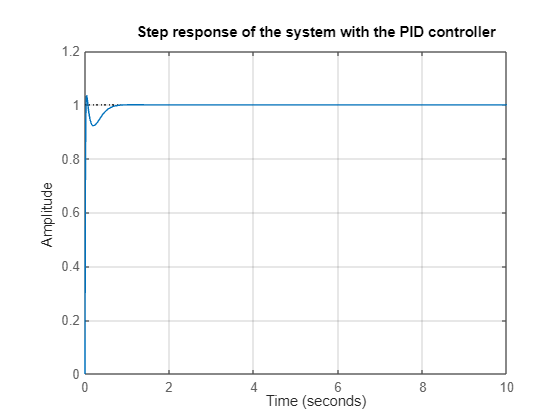

figure;
t = 0:0.01:10;
step(sys_closed, t);
grid on;
title('Step response of the system with the PID controller');

## Verification of stability margins

We plot the Bode Plot of the closed loop.

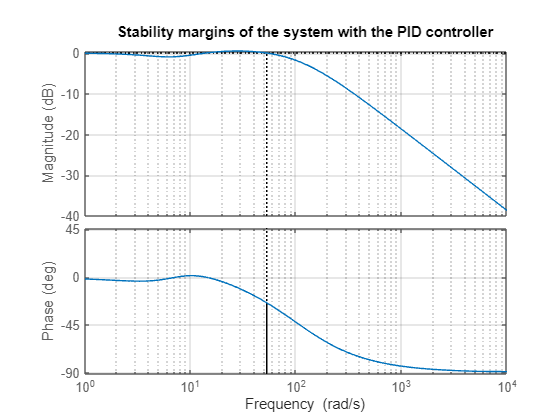

figure;
margin(sys_closed);
grid on;
title('Stability margins of the system with the PID controller');

## Simulation

% Pre-allocate arrays to store simulation results
time = 10.0;
% tSpan = linspace(0, time, time/dt); % Time vector with sampling rate of 100Hz
z_ref = params.z_eq + 0.05; % Reference position for control
num_steps = time/dt;
t_result = zeros(num_steps, 1); % Time vector to store simulation time
u_signal = zeros(num_steps, 1); % Control signal vector
x_result = zeros(num_steps, 2); % Matrix to store magnet position and velocity

% Control loop
t_current = 0.0;
x_current = [z0; 0]; % Initial state vector [position; velocity]
for i = 1:num_steps
    % Calculate error
    error = z_ref - x_current(1);
    
    % Calculate integral and derivative terms
    integral = integral + error * dt;
    derivative = (error - prev_error) / dt;
    
    % Calculate control signal using PID controller
    u = Kp * error + Ki * integral + Kd * derivative;
    
    % Update previous error
    prev_error = error;
    
    % Store current time and state
    t_result(i) = t_current;
    x_result(i, :) = x_current;
    
    % Update state using ODE integration
    [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
    
    % Update current time and state for next iteration
    t_current = t_out(end);
    x_current = x_out(end, :);
end

fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation 

Simulation time: 1.52s


### Plotting results

We plot the position of the center of the magnet to see the results of the simulation. 

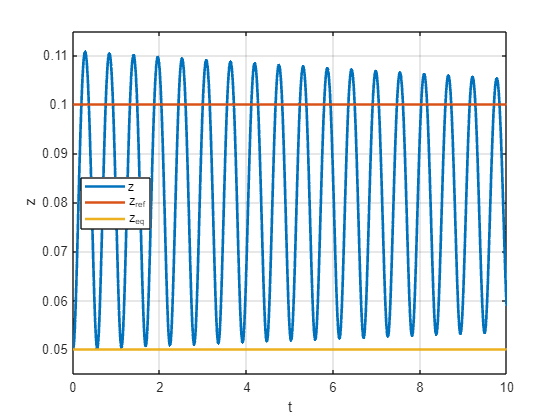

figure;
clf; grid on; hold on; box on;

plot(t_result, x_result(:, 1),'linewidth',2)
plot(t_result, z_ref * ones(num_steps,1),'linewidth',2)
plot(t_result, params.z_eq * ones(num_steps,1),'linewidth',2)
legend({'z','z_{ref}','z_{eq}'},'location','best')
xlabel('t')
ylabel('z')

ylim([0.045 0.115])

## Maximum height reached

max_position_and_velocity=max(x_result);
max_position=max_position_and_velocity(:,1);
disp(['Maximum value of z:', num2str(max_position)])

Maximum value of z:0.11079


clear

# Fifth assignment

% Load parameters
load_parameters;

% Optimal max tracking error
error_max = 0.002;

% Define the simulation time step
dt = 0.01;

% Start recording how much time the simulation takes
tic

% Initialize variables for control loop
prev_error = 0;
integral = 0;
z0 = params.z_eq; % Initial condition for magnet position

% Initialize open loop
numerator = params.b_s/params.z_eq;
denominator = [params.m params.d params.b_m/(params.z_eq)^2];
sys_open = tf(numerator,denominator);

## Create the PID controller

% pidTuner(sys_open, 'PID') % requires the Control System Toolbox add-on
Kp = 5.0;
Ki = 14;
Kd = 0.45;
C = pid(Kp,Ki,Kd);

% Closed loop
sys_closed = feedback(C*sys_open,1);

## Step response simulation

figure;
t = 0:0.01:10;
step(sys_closed, t);
grid on;
title('Step response of the system with the PID controller');

## Verification of stability margins

We plot the Bode Plot of the closed loop.

figure;
margin(sys_closed);
grid on;
title('Stability margins of the system with the PID controller');

## Simulation - $1^{\textrm{st}} \;\textrm{trajectory}$

Simulation of the levitating magnet tracking the reference trajetory

- 
$$z_{\textrm{ref}} \left(t\right)=z_0 +0\ldotp 01\sin \left(2\pi t\right)$$


% Pre-allocate arrays to store simulation results
time = 10.0;
tSpan = linspace(0, time, time/dt); % Time vector with sampling rate of 100Hz
num_steps = time/dt;
t_result = zeros(num_steps, 1); % Time vector to store simulation time
x_result = zeros(num_steps, 2); % Matrix to store magnet position and velocity
error_sig = zeros(num_steps, 1); % Error signal vector

% Control loop
t_current = 0.0;
x_current = [z0; 0]; % Initial state vector [position; velocity]
for i = 1:num_steps
    % Reference position for control 
    z_ref = params.z_eq + 0.01*sin(2*pi*t_current);
    
    % Calculate error
    error = z_ref - x_current(1);
    error_sig(i) = error;
    
    % Calculate integral and derivative terms
    integral = integral + error * dt;
    derivative = (error - prev_error) / dt;
    
    % Calculate control signal using PID controller
    u = Kp * error + Ki * integral + Kd * derivative;
    
    % Update previous error
    prev_error = error;
    
    % Store current time and state
    t_result(i) = t_current;
    x_result(i, :) = x_current;
    
    % Update state using ODE integration
    [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
    
    % Update current time and state for next iteration
    t_current = t_out(end);
    x_current = x_out(end, :);
end

fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time

Simulation time: 1.29s


### Plotting results

We plot the position of the center of the magnet to see the results of the simulation. 

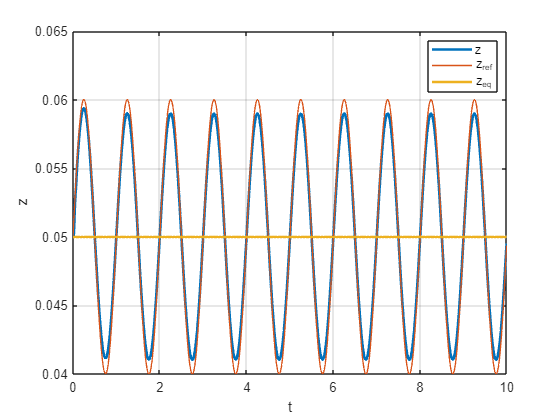

figure;
clf; grid on; hold on; box on;

plot(t_result, x_result(:, 1),'linewidth',2)
plot(t_result, 0.01*sin(2*pi*t_result) + params.z_eq,'linewidth',1)
plot(t_result, params.z_eq * ones(num_steps,1),'linewidth',2)
legend({'z','z_{ref}', 'z_{eq}'},'location','best')
xlabel('t')
ylabel('z')

### Tracking error plot

We plot the tracking error, which should be less than 2 millimiters (`error_max`) to have a "good enough" controller.

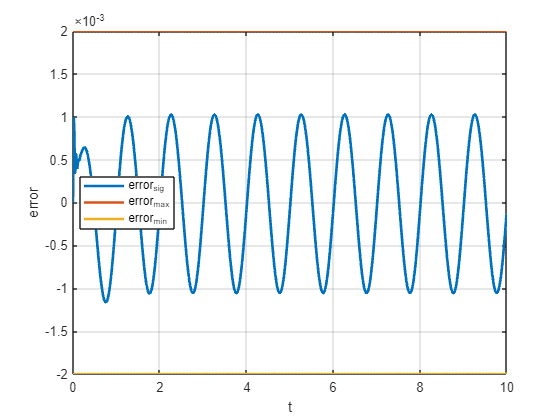

figure
clf; grid on; hold on; box on;

plot(t_result, error_sig,'linewidth',2)
plot(t_result, error_max * ones(num_steps,1),'linewidth',2)
plot(t_result, -error_max * ones(num_steps,1),'linewidth',2)
legend({'error_{sig}','error_{max}','error_{min}'},'location','best')
ylabel('error')
xlabel('t')

## Simulation - $2^{\textrm{nd}} \;\textrm{trajectory}$

Simulation of the levitating magnet tracking the reference trajetory

- 
$$z_{\textrm{ref}} \left(t\right)=z_0 +0\ldotp 01\textrm{squarewave}\left(2\pi t\right)$$


t_current = 0.0;
x_current = [z0; 0]; % Initial state vector [position; velocity]
for i = 1:num_steps
    % Reference position for control 
    z_ref = params.z_eq + 0.01*square(2*pi*t_current); % requires the Signal Processing Toolbox add-on
    
    % Calculate error
    error = z_ref - x_current(1);
    error_sig(i) = error;
    
    % Calculate integral and derivative terms
    integral = integral + error * dt;
    derivative = (error - prev_error) / dt;
    
    % Calculate control signal using PID controller
    u = Kp * error + Ki * integral + Kd * derivative;
    
    % Update previous error
    prev_error = error;
    
    % Store current time and state
    t_result(i) = t_current;
    x_result(i, :) = x_current;
    
    % Update state using ODE integration
    [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
    
    % Update current time and state for next iteration
    t_current = t_out(end);
    x_current = x_out(end, :);
end

fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time

Simulation time: 1.96s


### Plotting results

We plot the position of the center of the magnet to see the results of the simulation. 

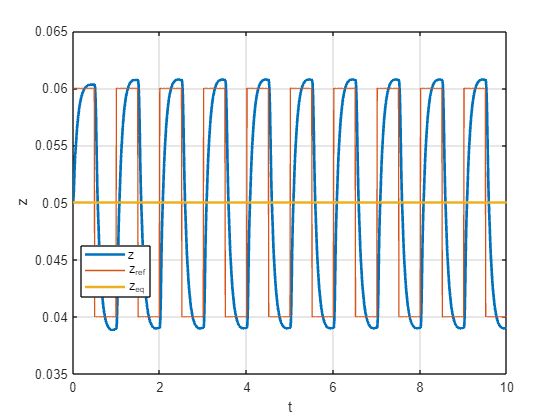

figure;
clf; grid on; hold on; box on;

plot(t_result, x_result(:, 1),'linewidth',2)
plot(t_result, 0.01*square(2*pi*t_result) + params.z_eq,'linewidth',1)
plot(t_result, params.z_eq * ones(num_steps,1),'linewidth',2)
legend({'z','z_{ref}', 'z_{eq}'},'location','best')
xlabel('t')
ylabel('z')

### Tracking error plot

We plot the tracking error, which should be less than 2 millimiters (`error_max`) to have a "good enough" controller.

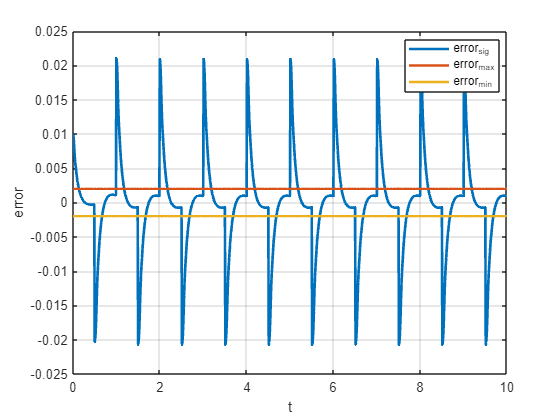

figure
clf; grid on; hold on; box on;

plot(t_result, error_sig,'linewidth',2)
plot(t_result, error_max * ones(num_steps,1),'linewidth',2)
plot(t_result, -error_max * ones(num_steps,1),'linewidth',2)
legend({'error_{sig}','error_{max}','error_{min}'},'location','best')
ylabel('error')
xlabel('t')